x5hr_data = load("C:\Users\ritur\Downloads\5hr_data.mat");
imu_data = x5hr_data.imu_data;

Fs = 40

Fs = 40

t0 = 1/Fs;

numReadings = length(imu_data);  % Total number of readings
ang_x = zeros(numReadings, 1);
ang_y = zeros(numReadings, 1);
ang_z = zeros(numReadings, 1);

for i = 1:numReadings
    ang_x(i) = imu_data{i}.imu.angular_velocity.x;
    ang_y(i) = imu_data{i}.imu.angular_velocity.y;
    ang_z(i) = imu_data{i}.imu.angular_velocity.z;
end

omega = ang_z % or ang_x or ang_y

omega =     0.0001
   -0.0004
   -0.0009
    0.0003
    0.0009
    0.0002
    0.0004
    0.0014
   -0.0002
   -0.0004


## Allan Variance Calculations

theta = cumsum(omega)*t0;
maxNumM = 100;
L = size(theta, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum( ...
        (theta(1+2*mi:L) - 2*theta(1+mi:L-mi) + theta(1:L-2*mi)).^2, 1);
end
avar = avar ./ (2*tau.^2 .* (L - 2*m));

## Allan deviation

adev = sqrt(avar);

[avarFromFunc, tauFromFunc] = allanvar(omega, m, Fs);
adevFromFunc = sqrt(avarFromFunc);



## Noise Parameters Identification

## Angle Random Walk

slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 1.0069e-04


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);




## Rate Random Walk

slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 1.2795e-07


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);



## Bias Instability

slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 7.0208e-06


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));

N

N = 1.0069e-04

K

K = 1.2795e-07

B

B = 7.0208e-06

## Allan Deviation with Noise Parameters

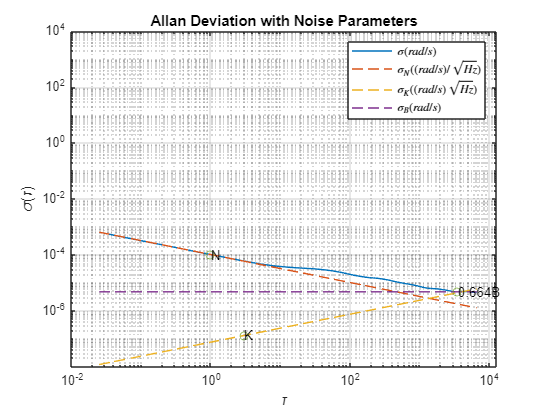

tauParams = [tauN, tauK, tauB];
params = [N, K, scfB*B];
figure
loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('$\sigma (rad/s)$', '$\sigma_N ((rad/s)/\sqrt{Hz})$', ...
    '$\sigma_K ((rad/s)\sqrt{Hz})$', '$\sigma_B (rad/s)$', 'Interpreter', 'latex')
text(tauParams, params, {'N', 'K', '0.664B'})
grid on
axis equal
print(gcf, 'ang_z', '-dpng', '-r300'); % High resolution PNG